# 1: Introduction

Data was recorded as described in the manuscript. For spikesorting we used Herdingspikes 2 (HS2, [https://homepages.inf.ed.ac.uk/mhennig/herdingspikes/](https://homepages.inf.ed.ac.uk/mhennig/herdingspikes/)) and we restructured the HS2 output format to two Matlab data structures -channelNames and spiketimestamps. The provided example scripts work only with these with two data formats but here I will give a good description how to re-create them with your data. All example data can be downloaded from Zenodo:** (put link and doi)**

**NB: HS2 provides the physical spike location which is crucial for our RGC classification. If you use another spike sorter without that "current sink" information, you may need to calculate the electrical image and the point of the current sink (x, y location). I will add an example script in the folder how to do that.**

# 2: The two data structures

#### channelNames 

*6 x (number of units) cell array; *channelNames is storing information about unit ID, location and activity parameters. I separated it from spiketimestamps (see below) because I found it more convenient (and faster) to have the spiketimestamps as a numeric integer array. channelNames is a legend to spiketimestamps. If you want to re-create it, see my description and example below:

- row 1: *'cluster name'  - *(character, with name of unit e.g. 'Cluster0122') 

- row 2: *'x pos (cluster centre)'  - *(number (float), x axis position of you spike cluster (grom HS2) on the MEA electrode grid) 

- row 3: *'y pos (cluster centre)'  - *(number (float), y axis position of you spike cluster (grom HS2) on the MEA electrode grid) 

- row 3: *'cluster number'  - *(number (float), with number of unit e.g. 'Cluster0122' would be 122) 

- row 4: *'total spikes/sec' - *(number (float), total spikes/sec) 

- row 5: *'total spikes no' - *(number (float), total spikes number) 

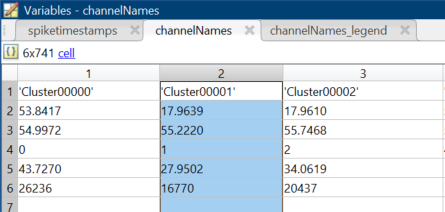

#### spiketimestamps

(max number of spikes) x (number of units) double array spiketimestamps is a integer matrix that contains the time of the spikes represented as data aquisition points. If you divide these intergers with the sampling rate you get the spike times in seconds. For each unit, the spike count was summed, and the max value was set to the row length. The remaining rows for all the other units was set to zero. 

- Rows are spike time stamps (integers, data aquisition points --> NOT time), empty arrays filled with zeros

- Columns for each unit - NB column organisation is identical to channelNames, hence channelkNames can be used as legend for spiketimestamps.  

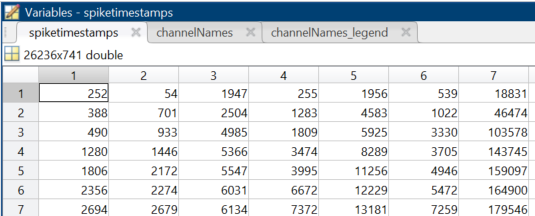

# 3: Load the two data structures

To find the DREADD induced changes of RGC firing, I used recordings (5 min) without light stimulation (spontaneous evoked activity) from control experiments and in the presence of 20 microM CNO. All data can be downloaded from Zenodo (see above). 

% Main data folders
clear
% where you stored the downloaded example data
datafolder = ['D:\Dropbox\Projects\Leverhulme\Leverhulmeproject_draft\Final\Resubmission\NewMatlabCode\ExampleData'];
% where you store the output
outfolder = ['D:\Dropbox\Projects\Leverhulme\Leverhulmeproject_draft\Final\Resubmission\NewMatlabCode\ExampleData\outfolder'];
mkdir(outfolder);


% File name channelNames control
clearvars channelNames
load(strcat(datafolder,...
    '\channelNames_P139_24_09_19_Scnn1aGQ_right_spont_ctl_clustered.mat'));
names1=channelNames;
% File name channelNames CNO
clearvars channelNames
load(strcat(datafolder,...
    '\channelNames_P139_24_09_19_Scnn1aGQ_right_spont_cno_clustered.mat'));
names2=channelNames;
clearvars channelNames
% File name spiketimestamps control
clearvars spiketimestamps
load(strcat(datafolder,...
    '\spiketimestamps_P139_24_09_19_Scnn1aGQ_right_spont_ctl_clustered.mat'));
spikes1=spiketimestamps/Sampling; % Sampling = sampling rate;
% File name spiketimestamps CNO
clearvars spiketimestamps
load(strcat(datafolder,...
    '\spiketimestamps_P139_24_09_19_Scnn1aGQ_right_spont_cno_clustered.mat'));
spikes2=spiketimestamps/Sampling;
clearvars spiketimestamps

disp('done loading data')

done loading data


# 4: Mean & median firing rates

DREADD activated (by CNO) RGCs should change their spike firing rate, indirect by DREADD ACs or direct by intrinsic factors. Hence, this part calculates  the spike firing rate of each RGC in control and CNO condition. For this, it is important to split the recorded data into smaller chunks (each 100 seconds longs, in total 6 x 100 sec (=5 min)) and calculate the total mean, ISI's and median spikes/sec from these chunks. Splitting the data in smaller chunks allows also to exclude outliers (artefacts etc). At the end, we store everything in a new matrix called goodunits.

% define some variables for later
clearvars reclength recblocks recblockslength
reclength = round(max(max(spikes1)));
recblocks=ceil(linspace(0,reclength,round(reclength/100)+1));
recblockslength=ceil(mean(diff(recblocks)));

% not all units are good - select the one that have a minimum of spikes
clearvars guidx goodunits myspiketreshold median_rb_ctl_freq mean_rb_ctl_freq...
    median_rb_cno_freq mean_rb_cno_freq mean_rb_ctl_freq median_rb_cno_freq...
    mean_rb_freq_change median_rb_freq_change
myspiketreshold = 24; % min 4 spikes per recblock needed (4 x 6 = 24) 
% - arbitrary threshold but we can expect to have a 
% lively RGC more than 24 spikes in 5 min (0.08 spikes/sec). 
% Further, 4 spikes per blcok is also required for calculating the burst
% index in the next part
guidx=find(cell2mat(names1(6,:))>=myspiketreshold); 
goodunits=names1(1:4,guidx);

% preallocation of variables
rb_1_ctl(1:length(spikes1(:,1)),1:length(goodunits))=zeros;
rb_2_ctl(1:length(spikes1(:,1)),1:length(goodunits))=zeros;
rb_3_ctl(1:length(spikes1(:,1)),1:length(goodunits))=zeros;
rb_4_ctl(1:length(spikes1(:,1)),1:length(goodunits))=zeros;
rb_5_ctl(1:length(spikes1(:,1)),1:length(goodunits))=zeros;
rb_6_ctl(1:length(spikes1(:,1)),1:length(goodunits))=zeros;

rb_1_cno(1:length(spikes1(:,1)),1:length(goodunits))=zeros;
rb_2_cno(1:length(spikes1(:,1)),1:length(goodunits))=zeros;
rb_3_cno(1:length(spikes1(:,1)),1:length(goodunits))=zeros;
rb_4_cno(1:length(spikes1(:,1)),1:length(goodunits))=zeros;
rb_5_cno(1:length(spikes1(:,1)),1:length(goodunits))=zeros;
rb_6_cno(1:length(spikes1(:,1)),1:length(goodunits))=zeros;

rb_ctl_freq(1:length(goodunits),1:6)=zeros;
rb_cno_freq(1:length(goodunits),1:6)=zeros;
median_rb_ctl_freq(1,1:length(goodunits))={0};
mean_rb_ctl_freq(1,1:length(goodunits))={0};
median_rb_cno_freq(1,1:length(goodunits))={0};
mean_rb_cno_freq(1,1:length(goodunits))={0};
median_rb_freq_change(1,1:length(goodunits))={0};
mean_rb_freq_change(1,1:length(goodunits))={0};

% Calculating the variables while in the loop
for i = 1:length(goodunits)
    tmpdata1=diff(spikes1(spikes1(:,guidx(i))>recblocks(1) & spikes1(:,guidx(i))<...
        recblocks(2),guidx(i)));
    rb_ctl_freq(i,1)=numel(tmpdata1)/round(recblockslength);
    rb_1_ctl(1:length(tmpdata1),i)=tmpdata1;
    clearvars tmpdata1
    
    tmpdata2=diff(spikes1(spikes1(:,guidx(i))>recblocks(2)&spikes1(:,guidx(i))<...
        recblocks(3),guidx(i)));
    rb_ctl_freq(i,2)=numel(tmpdata2)/round(recblockslength);
    rb_2_ctl(1:length(tmpdata2),i)=tmpdata2;
    clearvars tmpdata2
    
    tmpdata3=diff(spikes1(spikes1(:,guidx(i))>recblocks(3)&spikes1(:,guidx(i))<...
        recblocks(4),guidx(i)));
    rb_ctl_freq(i,3)=numel(tmpdata3)/round(recblockslength);
    rb_3_ctl(1:length(tmpdata3),i)=tmpdata3;
    clearvars tmpdata3
    
    tmpdata4=diff(spikes1(spikes1(:,guidx(i))>recblocks(4)&spikes1(:,guidx(i))<...
        recblocks(5),guidx(i)));
    rb_ctl_freq(i,4)=numel(tmpdata4)/round(recblockslength);
    rb_4_ctl(1:length(tmpdata4),i)=tmpdata4;
    clearvars tmpdata4
    
    tmpdata5=diff(spikes1(spikes1(:,guidx(i))>recblocks(5)&spikes1(:,guidx(i))<...
        recblocks(6),guidx(i)));
    rb_ctl_freq(i,5)=numel(tmpdata5)/round(recblockslength);
    rb_5_ctl(1:length(tmpdata5),i)=tmpdata5;
    clearvars tmpdata5
    
    tmpdata6=diff(spikes1(spikes1(:,guidx(i))>recblocks(6)&spikes1(:,guidx(i))<...
        recblocks(7),guidx(i)));
    rb_ctl_freq(i,6)=numel(tmpdata6)/round(recblockslength);
    rb_6_ctl(1:length(tmpdata6),i)=tmpdata6;
    clearvars tmpdata6
    
    % calculate the mean and median sppiking activity from CTL
    median_rb_ctl_freq{1,i}=nanmedian(rb_ctl_freq(i,:));
    mean_rb_ctl_freq{1,i}=nanmean(rb_ctl_freq(i,:));
    
    tmpdata1=diff(spikes2(spikes2(:,guidx(i))>recblocks(1)&spikes2(:,guidx(i))<...
        recblocks(2),guidx(i)));
    rb_cno_freq(i,1)=numel(tmpdata1)/round(recblockslength);
    rb_1_cno(1:length(tmpdata1),i)=tmpdata1;
    clearvars tmpdata1
    
    tmpdata2=diff(spikes2(spikes2(:,guidx(i))>recblocks(2)&spikes2(:,guidx(i))<...
        recblocks(3),guidx(i)));
    rb_cno_freq(i,2)=numel(tmpdata2)/round(recblockslength);
    rb_2_cno(1:length(tmpdata2),i)=tmpdata2;
    clearvars tmpdata2
    
    tmpdata3=diff(spikes2(spikes2(:,guidx(i))>recblocks(3)&spikes2(:,guidx(i))<...
        recblocks(4),guidx(i)));
    rb_cno_freq(i,3)=numel(tmpdata3)/round(recblockslength);
    rb_3_cno(1:length(tmpdata3),i)=tmpdata3;
    clearvars tmpdata3
    
    tmpdata4=diff(spikes2(spikes2(:,guidx(i))>recblocks(4)&spikes2(:,guidx(i))<...
        recblocks(5),guidx(i)));
    rb_cno_freq(i,4)=numel(tmpdata4)/round(recblockslength);
    rb_4_cno(1:length(tmpdata4),i)=tmpdata4;
    clearvars tmpdata4
    
    tmpdata5=diff(spikes2(spikes2(:,guidx(i))>recblocks(5)&spikes2(:,guidx(i))<...
        recblocks(6),guidx(i)));
    rb_cno_freq(i,5)=numel(tmpdata5)/round(recblockslength);
    rb_5_cno(1:length(tmpdata5),i)=tmpdata5;
    clearvars tmpdata5
    
    tmpdata6=diff(spikes2(spikes2(:,guidx(i))>recblocks(6)&spikes2(:,guidx(i))<...
        recblocks(7),guidx(i)));
    rb_cno_freq(i,6)=numel(tmpdata6)/round(recblockslength);
    rb_6_cno(1:length(tmpdata6),i)=tmpdata6;
    clearvars tmpdata6
    
    % calculate the mean and median sppiking activity from CNO
    median_rb_cno_freq{1,i}=nanmedian((rb_cno_freq(i,:)));
    mean_rb_cno_freq{1,i}=nanmean((rb_cno_freq(i,:)));
    
    % the percent of change between CTL and CNO
    median_rb_freq_change{1,i}=((median_rb_cno_freq{1,i}-median_rb_ctl_freq{1,i})/...
        median_rb_ctl_freq{1,i})*100;
    mean_rb_freq_change{1,i}=((mean_rb_cno_freq{1,i}-mean_rb_ctl_freq{1,i})/...
        mean_rb_ctl_freq{1,i})*100;
end

goodunits_legend =channelNames_legend(1:4,1);
goodunits_legend{5,1} = 'mean_rb_ctl_freq';
goodunits_legend{6,1} = 'mean_rb_cno_freq';
goodunits_legend{7,1} = 'mean_rb_freq_change';
goodunits_legend{8,1} = 'median_rb_ctl_freq';
goodunits_legend{9,1} = 'median_rb_cno_freq';
goodunits_legend{10,1} = 'median_rb_freq_change';

% have all the good ones in one place - keep the guidx!
goodunits = [goodunits;mean_rb_ctl_freq;mean_rb_cno_freq;mean_rb_freq_change;...
    median_rb_ctl_freq;median_rb_cno_freq;median_rb_freq_change];
goodspikes1 = spikes1(:,guidx);
goodspikes2 = spikes2(:,guidx);
goodnames1 = names1(:,guidx);
goodnames2 = names2(:,guidx);

save(strcat(outfolder,'\goodunits.mat'),"goodunits_legend","goodunits", "guidx",...
    "goodspikes1", "goodspikes2", "goodnames1", "goodnames2", "Sampling"); 
save(strcat(outfolder,'\recordingblocks.mat'),"rb_1_ctl", "rb_2_ctl", "rb_3_ctl",...
    "rb_4_ctl", "rb_5_ctl", "rb_6_ctl","rb_1_cno", "rb_2_cno", "rb_3_cno",...
    "rb_4_cno", "rb_5_cno", "rb_6_cno", "recblockslength"); 

disp('done calculating firing rates')

done calculating firing rates


# 5: Burst index

Firing rate is not the only feature that can be changed by activated DREADD cells but also the bursting pattern. It might be very well that no or no significant change of firing rate is detected but the burst pattern changed. That burts change is calculated here by the "Burst Index" which was introduced by Jones et al., 2007 (Spontaneous discharge patterns in cochlear spiral ganglion cells before the onset of hearing in cats; J Neurophysiol. 2007;98:1898–1908)


$$\textrm{BurstIndex}=\frac{\textrm{total}\;\textrm{time}\;\textrm{of}\;\;\textrm{longest}\;\textrm{intervals}\;}{\textrm{total}\;\textrm{sample}\;\textrm{time}}*\frac{\textrm{mean}\;\textrm{interval}\;\textrm{length}\;\textrm{of}\;\;\textrm{longest}\;\textrm{intervals}}{\frac{\textrm{total}\;\textrm{sample}\;\textrm{time}}{\;\textrm{total}\;\textrm{number}\;\textrm{of}\;\textrm{intervals}}}$$


In brief, a high Burst Index (BI) indicates more bursting. We will add the BI value to the goodunits matrix.

clearvars -except outfolder datafolder
load(strcat(outfolder,'\goodunits.mat'));
load(strcat(outfolder,'\recordingblocks.mat'));

%allocation of variables
A_ctl(1:length(goodunits),1:6)=zeros;
B_ctl(1:length(goodunits),1:6)=zeros;
BurstIdx_ctl(1:length(goodunits),1:6)=zeros;
sumBurstIdx_ctl(1,1:length(goodunits))={zeros};
sumBurstIdx_change(1,1:length(goodunits))={zeros};
A_cno(1:length(goodunits),1:6)=zeros;
B_cno(1:length(goodunits),1:6)=zeros;
BurstIdx_cno(1:length(goodunits),1:6)=zeros;
sumBurstIdx_cno(1,1:length(goodunits))={zeros};

for i = 1:length(goodunits)
    clearvars tmpdata Anum A05 longISItotalTime longISImeanTime
    tmpdata=sort(rb_1_ctl(:,i),'descend');
    tmpdata(tmpdata==0)=[];
    Anum = numel(tmpdata);
    A05 = round(Anum*0.05);
    % the longest intervals are used to claculate the BI
    % The four longest when Anum is less than 80 spikes and 5% over spikes
    % (and have min 4 spikes)
    if Anum < 80 && Anum >=4
        longISItotalTime=sum(tmpdata(1:4)); %total time of the longest intervals
        longISImeanTime=mean(tmpdata(1:4)); %mean interval length of the longest intervals
    else
        longISItotalTime=sum(tmpdata(1:A05));
        longISImeanTime=mean(tmpdata(1:A05));
    end
    % A represents the first part of the formula above, B the second part
    A_ctl(i,1) = longISItotalTime/recblockslength; %recblockslength = total sample time
    B_ctl(i,1) = longISImeanTime/(recblockslength/Anum);
    BurstIdx_ctl(i,1) = A_ctl(i,1)*B_ctl(i,1);
    
    % the next parts are repeats of the above one
    clearvars tmpdata Anum A05 longISItotalTime longISImeanTime
    tmpdata=sort(rb_2_ctl(:,i),'descend');
    tmpdata(tmpdata==0)=[];
    Anum = numel(tmpdata);
    A05 = round(Anum*0.05);
    if Anum < 80 && Anum >=4
        longISItotalTime=sum(tmpdata(1:4)); 
        longISImeanTime=mean(tmpdata(1:4)); 
    else
        longISItotalTime=sum(tmpdata(1:A05));
        longISImeanTime=mean(tmpdata(1:A05));
    end
    A_ctl(i,2) = longISItotalTime/recblockslength;
    B_ctl(i,2) = longISImeanTime/(recblockslength/Anum);
    BurstIdx_ctl(i,2) = A_ctl(i,2)*B_ctl(i,2);
    
    clearvars tmpdata Anum A05 longISItotalTime longISImeanTime
    tmpdata=sort(rb_3_ctl(:,i),'descend');
    tmpdata(tmpdata==0)=[];
    Anum = numel(tmpdata);
    A05 = round(Anum*0.05);
    if Anum < 80 && Anum >=4
        longISItotalTime=sum(tmpdata(1:4)); 
        longISImeanTime=mean(tmpdata(1:4)); 
    else
        longISItotalTime=sum(tmpdata(1:A05));
        longISImeanTime=mean(tmpdata(1:A05));
    end
    A_ctl(i,3) = longISItotalTime/recblockslength;
    B_ctl(i,3) = longISImeanTime/(recblockslength/Anum);
    BurstIdx_ctl(i,3) = A_ctl(i,3)*B_ctl(i,3);
    
    clearvars tmpdata Anum A05 longISItotalTime longISImeanTime
    tmpdata=sort(rb_4_ctl(:,i),'descend');
    tmpdata(tmpdata==0)=[];
    Anum = numel(tmpdata);
    A05 = round(Anum*0.05);
    if Anum < 80 && Anum >=4
        longISItotalTime=sum(tmpdata(1:4)); 
        longISImeanTime=mean(tmpdata(1:4)); 
    else
        longISItotalTime=sum(tmpdata(1:A05));
        longISImeanTime=mean(tmpdata(1:A05));
    end
    A_ctl(i,4) = longISItotalTime/recblockslength;
    B_ctl(i,4) = longISImeanTime/(recblockslength/Anum);
    BurstIdx_ctl(i,4) = A_ctl(i,4)*B_ctl(i,4);
    
    clearvars tmpdata Anum A05 longISItotalTime longISImeanTime
    tmpdata=sort(rb_5_ctl(:,i),'descend');
    tmpdata(tmpdata==0)=[];
    Anum = numel(tmpdata);
    A05 = round(Anum*0.05);
    if Anum < 80 && Anum >=4
        longISItotalTime=sum(tmpdata(1:4)); 
        longISImeanTime=mean(tmpdata(1:4)); 
    else
        longISItotalTime=sum(tmpdata(1:A05));
        longISImeanTime=mean(tmpdata(1:A05));
    end
    A_ctl(i,5) = longISItotalTime/recblockslength;
    B_ctl(i,5) = longISImeanTime/(recblockslength/Anum);
    BurstIdx_ctl(i,5) = A_ctl(i,5)*B_ctl(i,5);
    
    clearvars tmpdata Anum A05 longISItotalTime longISImeanTime
    tmpdata=sort(rb_6_ctl(:,i),'descend');
    tmpdata(tmpdata==0)=[];
    Anum = numel(tmpdata);
    A05 = round(Anum*0.05);
    if Anum < 80 && Anum >=4
        longISItotalTime=sum(tmpdata(1:4)); 
        longISImeanTime=mean(tmpdata(1:4)); 
    else
        longISItotalTime=sum(tmpdata(1:A05));
        longISImeanTime=mean(tmpdata(1:A05));
    end
    A_ctl(i,6) = longISItotalTime/recblockslength;
    B_ctl(i,6) = longISImeanTime/(recblockslength/Anum);
    BurstIdx_ctl(i,6) = A_ctl(i,6)*B_ctl(i,6);
    
    %the median of all recblocks bursting (avoiding outliers)
    sumBurstIdx_ctl{1,i} =nanmedian(BurstIdx_ctl(i,:));
    
    %%%%%%%%CNO%%%%%%%
    clearvars tmpdata Anum A05 longISItotalTime longISImeanTime
    tmpdata=sort(rb_1_cno(:,i),'descend');
    tmpdata(tmpdata==0)=[];
    Anum = numel(tmpdata);
    A05 = round(Anum*0.05);
    if Anum < 80 && Anum >=4
        longISItotalTime=sum(tmpdata(1:4)); 
        longISImeanTime=mean(tmpdata(1:4)); 
    else
        longISItotalTime=sum(tmpdata(1:A05));
        longISImeanTime=mean(tmpdata(1:A05));
    end
    A_cno(i,1) = longISItotalTime/recblockslength;
    B_cno(i,1) = longISImeanTime/(recblockslength/Anum);
    BurstIdx_cno(i,1) = A_cno(i,1)*B_cno(i,1);
    
    clearvars tmpdata Anum A05 longISItotalTime longISImeanTime
    tmpdata=sort(rb_2_cno(:,i),'descend');
    tmpdata(tmpdata==0)=[];
    Anum = numel(tmpdata);
    A05 = round(Anum*0.05);
    if Anum < 80 && Anum >=4
        longISItotalTime=sum(tmpdata(1:4)); 
        longISImeanTime=mean(tmpdata(1:4)); 
    else
        longISItotalTime=sum(tmpdata(1:A05));
        longISImeanTime=mean(tmpdata(1:A05));
    end
    A_cno(i,2) = longISItotalTime/recblockslength;
    B_cno(i,2) = longISImeanTime/(recblockslength/Anum);
    BurstIdx_cno(i,2) = A_cno(i,2)*B_cno(i,2);
    
    clearvars tmpdata Anum A05 longISItotalTime longISImeanTime
    tmpdata=sort(rb_3_cno(:,i),'descend');
    tmpdata(tmpdata==0)=[];
    Anum = numel(tmpdata);
    A05 = round(Anum*0.05);
    if Anum < 80 && Anum >=4
        longISItotalTime=sum(tmpdata(1:4)); 
        longISImeanTime=mean(tmpdata(1:4)); 
    else
        longISItotalTime=sum(tmpdata(1:A05));
        longISImeanTime=mean(tmpdata(1:A05));
    end
    A_cno(i,3) = longISItotalTime/recblockslength;
    B_cno(i,3) = longISImeanTime/(recblockslength/Anum);
    BurstIdx_cno(i,3) = A_cno(i,3)*B_cno(i,3);
    
    clearvars tmpdata Anum A05 longISItotalTime longISImeanTime
    tmpdata=sort(rb_4_cno(:,i),'descend');
    tmpdata(tmpdata==0)=[];
    Anum = numel(tmpdata);
    A05 = round(Anum*0.05);
    if Anum < 80 && Anum >=4
        longISItotalTime=sum(tmpdata(1:4)); 
        longISImeanTime=mean(tmpdata(1:4)); 
    else
        longISItotalTime=sum(tmpdata(1:A05));
        longISImeanTime=mean(tmpdata(1:A05));
    end
    A_cno(i,4) = longISItotalTime/recblockslength;
    B_cno(i,4) = longISImeanTime/(recblockslength/Anum);
    BurstIdx_cno(i,4) = A_cno(i,4)*B_cno(i,4);
    
    clearvars tmpdata Anum A05 longISItotalTime longISImeanTime
    tmpdata=sort(rb_5_cno(:,i),'descend');
    tmpdata(tmpdata==0)=[];
    Anum = numel(tmpdata);
    A05 = round(Anum*0.05);
    if Anum < 80 && Anum >=4
        longISItotalTime=sum(tmpdata(1:4)); 
        longISImeanTime=mean(tmpdata(1:4)); 
    else
        longISItotalTime=sum(tmpdata(1:A05));
        longISImeanTime=mean(tmpdata(1:A05));
    end
    A_cno(i,5) = longISItotalTime/recblockslength;
    B_cno(i,5) = longISImeanTime/(recblockslength/Anum);
    BurstIdx_cno(i,5) = A_cno(i,5)*B_cno(i,5);
    
    clearvars tmpdata Anum A05 longISItotalTime longISImeanTime
    tmpdata=sort(rb_6_cno(:,i),'descend');
    tmpdata(tmpdata==0)=[];
    Anum = numel(tmpdata);
    A05 = round(Anum*0.05);
    if Anum < 80 && Anum >=4
        longISItotalTime=sum(tmpdata(1:4)); 
        longISImeanTime=mean(tmpdata(1:4)); 
    else
        longISItotalTime=sum(tmpdata(1:A05));
        longISImeanTime=mean(tmpdata(1:A05));
    end
    A_cno(i,6) = longISItotalTime/recblockslength;
    B_cno(i,6) = longISImeanTime/(recblockslength/Anum);
    BurstIdx_cno(i,6) = A_cno(i,6)*B_cno(i,6);
    
    %the median of all recblocks bursting (avoiding outliers) 
    sumBurstIdx_cno{1,i} =nanmedian(BurstIdx_cno(i,:));
    % calculting the percent change while in the loop
    sumBurstIdx_change{1,i}=((sumBurstIdx_cno{1,i}-sumBurstIdx_ctl{1,i})/...
        sumBurstIdx_ctl{1,i})*100;
end

% extend the legend
goodunits_legend{11,1} = 'medianBurstIdx_ctl';
goodunits_legend{12,1} = 'medianBurstIdx_cno';
goodunits_legend{13,1} = 'medianBurstIdx_change';


% extend goodunits
goodunits = [goodunits;sumBurstIdx_ctl;sumBurstIdx_cno;sumBurstIdx_change];
save(strcat(outfolder,'\goodunits.mat'),"goodunits_legend","goodunits",...
    "guidx","goodspikes1", "goodspikes2", "goodnames1", "goodnames2", "Sampling"); 

disp('done calculating burst index')

done calculating burst index


# 6: Plotting the distribution of firing rates and BI

At some point a threshold is needed to define DREADD activated units. NB thatthreshold is just ONE criterion! The location of the unit is ANOTHER criterion! 

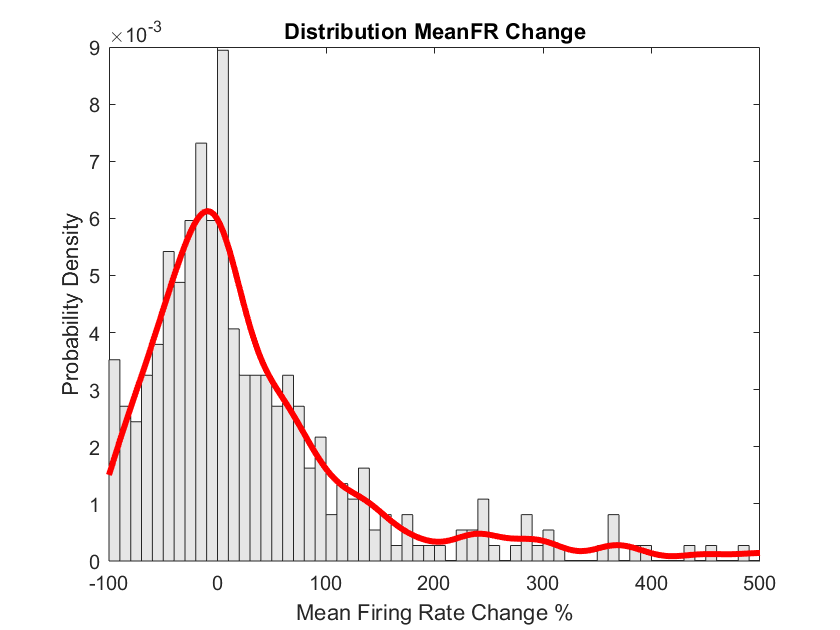


clearvars -except outfolder datafolder
load(strcat(outfolder,'\goodunits.mat'));

% the values we want to plot
% goodunits_legend{7,1} = 'mean_rb_freq_change';
% goodunits_legend{10,1} = 'median_rb_freq_change';
% goodunits_legend{13,1} = 'medianBurstIdx_change';

% start with mean firing rate change
clearvars mydata pdf_normmixture paramEsts xgrid pdfgrid minVal maxVal tmp3 pd
mydata = cell2mat(goodunits(7,:));
%plot histogram with fit
mydata(isinf(mydata))=[];
div=10;
minVal = -100;
maxVal = 500;
bins = minVal:div:maxVal;

tmp3 = histcounts(mydata,bins);
figure
h = bar(bins(1:end-1),tmp3/(length(mydata)*div),'histc');
h.FaceColor = [.9 .9 .9];
pd = fitdist(mydata','Kernel','Kernel','normal','Width', 20);
xgrid = linspace(minVal,maxVal,200);
pdfgrid = pdf(pd,xgrid);

hold on
plot(xgrid,pdfgrid,'-r','LineWidth',3)
hold off
xlabel('Mean Firing Rate Change %')
ylabel('Probability Density')
title('Distribution MeanFR Change')

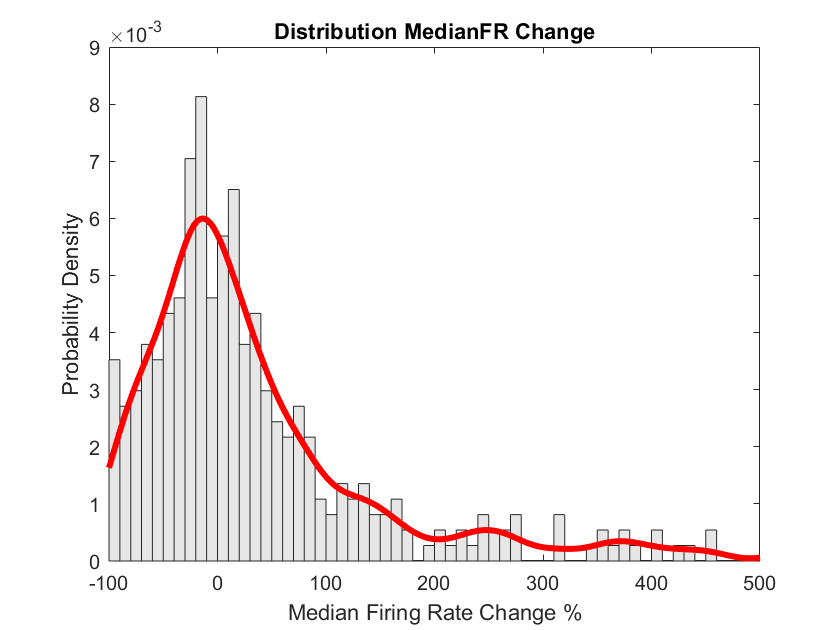

% median firing rate change
clearvars mydata pdf_normmixture paramEsts xgrid pdfgrid minVal maxVal tmp3 pd
mydata = cell2mat(goodunits(10,:));
%plot histogram with fit
mydata(isinf(mydata))=[];
div=10;
minVal = -100;
maxVal = 500;
bins = minVal:div:maxVal;

tmp3 = histcounts(mydata,bins);
figure
h = bar(bins(1:end-1),tmp3/(length(mydata)*div),'histc');
h.FaceColor = [.9 .9 .9];
pd = fitdist(mydata','Kernel','Kernel','normal','Width', 20);
xgrid = linspace(minVal,maxVal,200);
pdfgrid = pdf(pd,xgrid);

hold on
plot(xgrid,pdfgrid,'-r','LineWidth',3)
hold off
xlabel('Median Firing Rate Change %')
ylabel('Probability Density')
title('Distribution MedianFR Change')

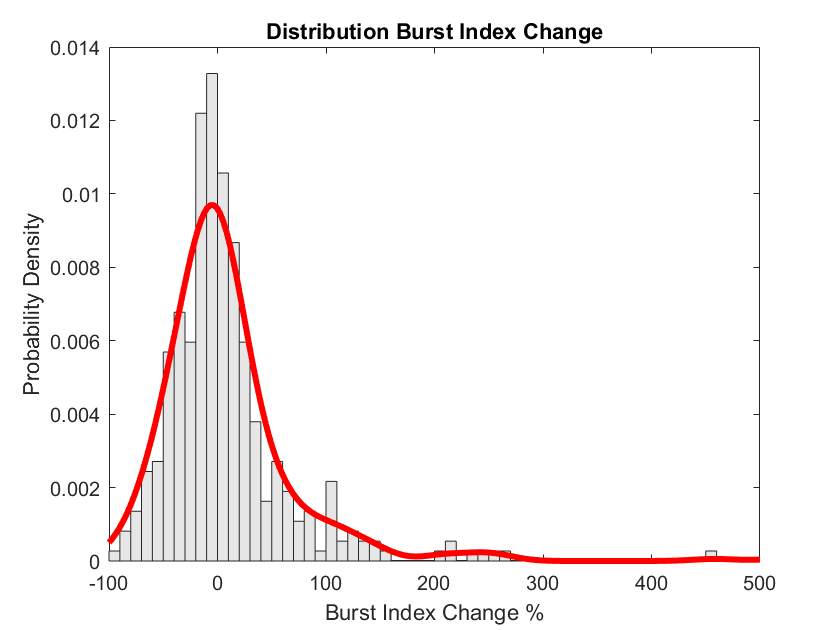


% burst index change
clearvars mydata pdf_normmixture paramEsts xgrid pdfgrid minVal maxVal tmp3 pd
mydata = cell2mat(goodunits(13,:));
%plot histogram with fit
mydata(isinf(mydata))=[];
div=10;
minVal = -100;
maxVal = 500;
bins = minVal:div:maxVal;

tmp3 = histcounts(mydata,bins);
figure
h = bar(bins(1:end-1),tmp3/(length(mydata)*div),'histc');
h.FaceColor = [.9 .9 .9];
pd = fitdist(mydata','Kernel','Kernel','normal','Width', 20);
xgrid = linspace(minVal,maxVal,200);
pdfgrid = pdf(pd,xgrid);

hold on
plot(xgrid,pdfgrid,'-r','LineWidth',3)
hold off
xlabel('Burst Index Change %')
ylabel('Probability Density')
title('Distribution Burst Index Change')

# 7: Plotting some example spike rasters

Seeing is believing, hence let's plot some spike trains. It is also good to estimate the thresholds for FR and BI (without knowing the location...which comes later). The plots show on the left side of the red line the CTL spontaneous activity and on the right side of the red line the CNO activity. Spikes are plotted as a line against the time they occur. 

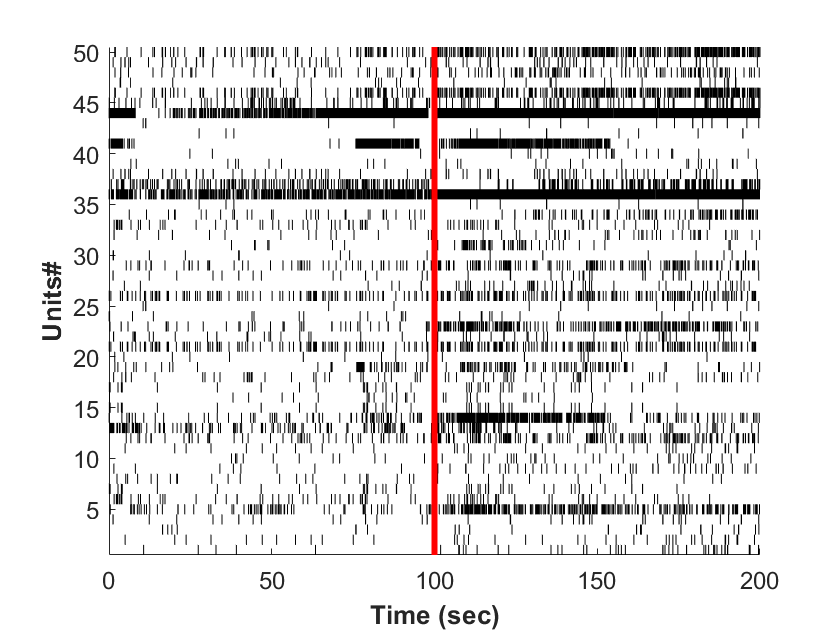

% mean FR
clearvars mydata mythreshold myidx myspikes1 myspikes2 numrandunits randclus...
    plotspikes2 plotspikes1
mydata = cell2mat(goodunits(7,:)); 
mythreshold = +50; % in percent
range=[100 200]; % defines the time window of our raster - the same for CTL and CNO
addtime=diff(range);
myidx = find(mydata>mythreshold);
myspikes1 = goodspikes1(:,myidx);
myspikes2 = goodspikes2(:,myidx);
numrandunits = 50; % plot no random thresholded units
randclus=randi(length(myspikes1(1,:)),[1,numrandunits]);

trains = 1:numrandunits;
ii=1;
figure
for i = trains
    clearvars plotspikes1 plotspikes2 myind1 myind2 t
    myind1 = myspikes1(:,randclus(i))>=range(1) & myspikes1(:,randclus(i))<range(2);
    plotspikes1 = myspikes1(myind1,randclus(i))-range(1);
    myind2 = myspikes2(:,randclus(i))>=range(1) & myspikes2(:,randclus(i))<range(2);
    plotspikes2 = myspikes2(myind2,randclus(i))-(range(1)-addtime);
    t=vertcat(plotspikes1, plotspikes2);
    if isempty(t)==0
%         ll(i,:)=histcounts(t,edges);
        nspikes   = numel(t);
        for ii = 1:nspikes
            line([t(ii) t(ii)],[i-0.5 i+0.5],'Color','k','LineWidth',0.25);
            hold on
        end
        line([addtime addtime],[i-0.5 i+0.5],'Color','r','LineWidth',3);
        hold on
    else
        line([addtime addtime],[i-0.5 i+0.5],'Color','r','LineWidth',3);
        hold on
    end
    ii = ii+1;
end
set(gca,'YLim',[0.5 max(length(trains))+0.5]);
ylabel('Units#','fontsize',12,'fontweight','b');
xlabel('Time (sec)','fontsize',12,'fontweight','b');
set(gca,'fontsize',12)

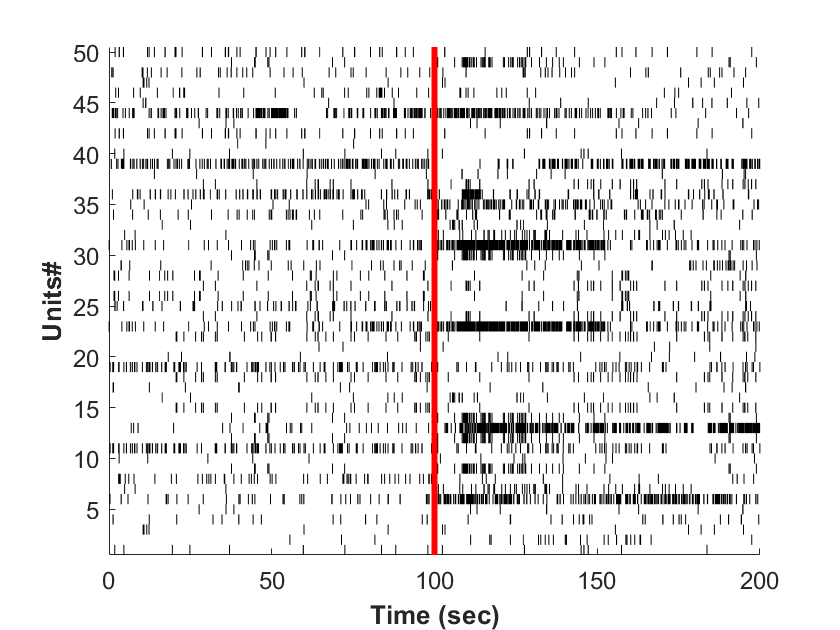


% Burst Index
clearvars mydata mythreshold myidx myspikes1 myspikes2 numrandunits randclus...
    plotspikes2 plotspikes1
mydata = cell2mat(goodunits(13,:)); 
mythreshold = +50; % in percent
range=[100 200]; % defines the time window of our raster - the same for CTL and CNO
addtime=diff(range);
myidx = find(mydata>mythreshold);
myspikes1 = goodspikes1(:,myidx);
myspikes2 = goodspikes2(:,myidx);
numrandunits = 50; % plot no random thresholded units
randclus=randi(length(myspikes1(1,:)),[1,numrandunits]);

trains = 1:numrandunits;
ii=1;
figure
for i = trains
    clearvars plotspikes1 plotspikes2 myind1 myind2 t
    myind1 = myspikes1(:,randclus(i))>=range(1) & myspikes1(:,randclus(i))<range(2);
    plotspikes1 = myspikes1(myind1,randclus(i))-range(1);
    myind2 = myspikes2(:,randclus(i))>=range(1) & myspikes2(:,randclus(i))<range(2);
    plotspikes2 = myspikes2(myind2,randclus(i))-(range(1)-addtime);
    t=vertcat(plotspikes1, plotspikes2);
    if isempty(t)==0
%         ll(i,:)=histcounts(t,edges);
        nspikes   = numel(t);
        for ii = 1:nspikes
            line([t(ii) t(ii)],[i-0.5 i+0.5],'Color','k','LineWidth',0.25);
            hold on
        end
        line([addtime addtime],[i-0.5 i+0.5],'Color','r','LineWidth',3);
        hold on
    else
        line([addtime addtime],[i-0.5 i+0.5],'Color','r','LineWidth',3);
        hold on
    end
    ii = ii+1;
end
set(gca,'YLim',[0.5 max(length(trains))+0.5]);
ylabel('Units#','fontsize',12,'fontweight','b');
xlabel('Time (sec)','fontsize',12,'fontweight','b');
set(gca,'fontsize',12)

# 8: Conclusion

At the end of this cript you should have a matrix (goodunits) that gives the information about firing rate and Burst Index change after application of CNO. Alone, it will not help to isolate and classify DREADD RGCs. Hence, we need more information. In the next script, I will use microscope images of the GFP cells and correlate it with the MEA recordings. Together with the here aquired information, DREADD RGCs will be isolated and classified